# SIR Notebook 3: Verification and Validation

*Author:* Zachary del Rosario, Fall 2020

*Learning Objectives:* As a result of working through this notebook, you will learn:

- A productive mindset for model verification and validation

- Example checks we can run for *verification*

- What it looks like when there are *missing physics* in our model (an example of *validation*)

## Model Recap

In the previous notebook we studied some data from a scenario and used it to fit a Susceptible, Infected, Recovered (SIR) model:

% Load the training data
tab_data_train = readtable("infected.csv", "Delimiter", ",")

tab_data_train = 6×2 table
    W    I 
    _    __

    1     2
    2     3
    3     5
    4     8
    5    11
    6    16


We fit an SIR model to those data, and used it to make a prediction.

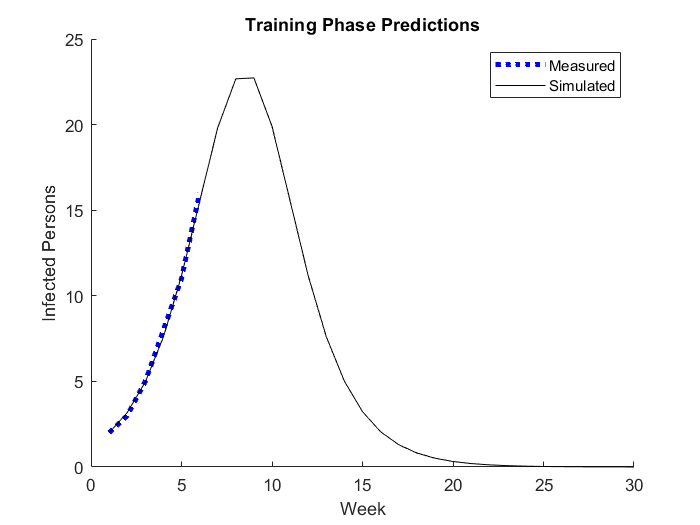

% NOTE: The following is my fitted model
beta = 1 / 90; % Infection rate (New / Susceptible / Infected / day)
gamma = 1 / 2; % Recovery rate (1 / day)
i_0 = 2;       % Initial count of infected persons

% Define initial state
s_0 = 100 - i_0;
r_0 = 0;

% Run simulation
[S_fit, I_fit, R_fit, W_fit] = sir_simulate(s_0, i_0, r_0, beta, gamma, 30);

% Plot the fitted simulation
figure(1); clf; hold on;
plot(tab_data_train.W, tab_data_train.I, 'b:', 'LineWidth', 3); label1 = "Measured";
plot(W_fit, I_fit, 'k-'); label2 = "Simulated";

xlabel("Week")
ylabel("Infected Persons")
legend({label1, label2})
title("Training Phase Predictions")

While the overlap of Measured and Simulated data is *encouraging*, we should maintain a healthy dose of skepticism towards these model results until we *verify* and *validate* the model.

Remember that:

- **Verification** is checking that we *implemented the model correctly*; it's an exercise in coding / math.

- **Validation** is checking that *the model represents reality*; it's an exercise in physics.

ModSim students in 2020 came up with some good mnemonics:

- Verifi**c**ation concerns **c**ode

- Vali**d**ation concerns physical **d**ata

Let's look at some examples of verification and validation!

**Verification Steps:** To build and verify a physical model, we should follow a set of steps:

- *Clearly state* the model in *abstract* terms: the full set of governing equations that define the model.

- *Implement* the model in computer code, for example Matlab

- *Decide* on a set of "facts" about the model results that should be true, based on the *abstract* definition of the model

- *Verify* that the model satisfies those "facts"

Remember that *verification* is an exercise in software development / mathematics: We are *not yet *comparing our model against physical data. Instead, we're just checking to make sure we implemented the model correctly.

Remember back to the Penny Myth example: With Model 1 (the drag-free one) we *verified* our model results by checking that the distance the penny fell matched the height of the Empire State Building. That's a "fact" about the model results we know should be true, based on the way we set up the problem.

Writing down a set of "facts" about our model requires that we have some knowledge about our model. For example, when we derived the SIR model equations in `sir_notebook1.mlx`, we took great pains to make sure we didn't lose any individuals. As a reminder, those equations were:


$$S_{t+1} = S_t - \Delta I_t \\
I_{t+1} = I_t + \Delta I_t - \Delta R_t \\
R_{t+1} = R_t + \Delta R_t$$


Since the change terms $\Delta I, \Delta R$ are added and subtracted are carefully balanced across the stocks, the total number of persons should be *conserved*.

**Exercise:** Write down a mathematical expression for the *total number of persons* in the SIR model, based on the stocks $S, I, R$. Compute your expression using `S_fit, I_fit, R_fit` (computed above). Does this model conserve the total number of persons?

*total s + total i + total r should always be the same*

*(Here's some space for you to write some math using text!)*

% TODO: Compute total persons, plot
% HINT 1: You can copy-paste plotting code from above!
% HINT 2: Your plot might end up looking "boring"....
% NOTE: The following is my fitted model
beta = 1 / 90; % Infection rate (New / Susceptible / Infected / day)
gamma = 1 / 2; % Recovery rate (1 / week)
i_0 = 2;       % Initial count of infected persons

% Define initial state
s_0 = 100 - i_0;
r_0 = 0;

% Run simulation
[S_fit, I_fit, R_fit, W_fit] = sir_simulate(s_0, i_0, r_0, beta, gamma, 30)

S_fit =    98.0000   95.8222   92.4389   87.3319   79.9639   70.0443   57.9797   45.2142   33.8235   25.2822   19.6907   16.2899   14.2676   13.0614   12.3342   11.8913   11.6192   11.4511   11.3469   11.2822   11.2419   11.2167   11.2011   11.1913   11.1852   11.1814   11.1790   11.1776   11.1766   11.1761


I_fit =     2.0000    3.1778    4.9722    7.5931   11.1646   15.5018   19.8155   22.6733   22.7273   19.9049   15.5440   11.1728    7.6087    5.0105    3.2324    2.0592    1.3017    0.8189    0.5136    0.3216    0.2011    0.1257    0.0785    0.0490    0.0306    0.0191    0.0119    0.0074    0.0046    0.0029


R_fit =          0    1.0000    2.5889    5.0750    8.8716   14.4538   22.2048   32.1125   43.4492   54.8128   64.7653   72.5373   78.1237   81.9281   84.4333   86.0495   87.0791   87.7300   88.1394   88.3962   88.5570   88.6576   88.7204   88.7597   88.7842   88.7995   88.8090   88.8150   88.8187   88.8210


W_fit =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


total_fit = S_fit + I_fit + R_fit

total_fit =   100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000


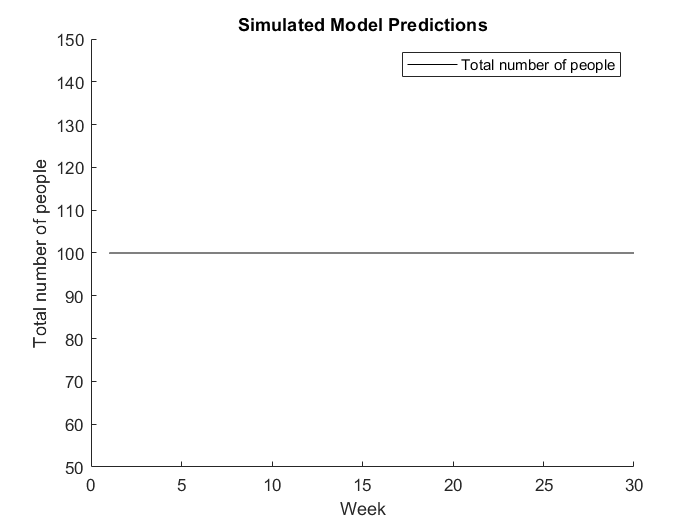


% Plot the fitted simulation
figure(1); clf; hold on;
plot(W_fit, total_fit, 'k-'); label2 = "Total number of people"; % plot total number of people

xlabel("Week")
ylabel("Total number of people")
legend(label2)
ylim([50 150])
title("Simulated Model Predictions")

However, as some students in 2020's class found, this conservation doesn't hold for **all parameter values:**

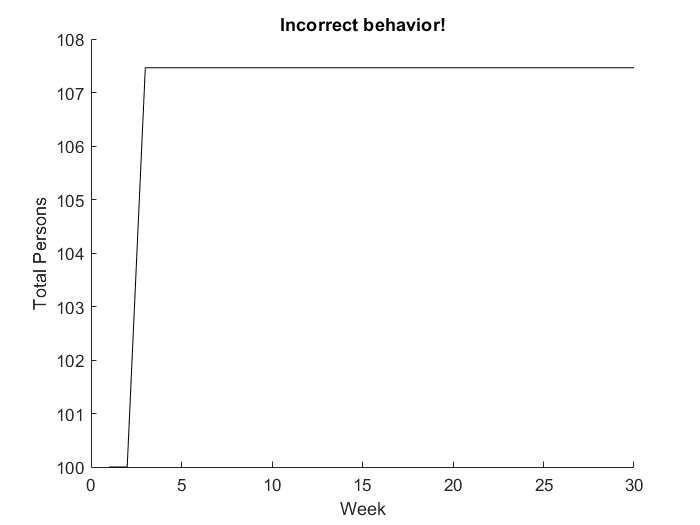

% NOTE: The following is my fitted model
beta = 1 / 10;  % Infection rate (New / Susceptible / Infected / day)
gamma = 1 / 16; % Recovery rate (1 / day)
i_0 = 1;        % Initial count of infected persons

% Define initial state
s_0 = 100 - i_0;
r_0 = 0;

% Run simulation
[S_iv, I_iv, R_iv, W_iv] = sir_simulate(s_0, i_0, r_0, beta, gamma, 30);
T_iv = S_iv + I_iv + R_iv;

% Plot the problematic results
figure(2); clf; hold on;
plot(W_iv, T_iv, 'k-');

xlabel("Week")
ylabel("Total Persons")
title("Incorrect behavior!")

This is because the correctness of the $\Delta I, \Delta R$ terms is not enforced well; the following code from `sir_step.m`

% This way of enforcing invariants does not actually conserve persons!
%s_n = max(s_n, 0);
%i_n = max(i_n, 0);
%r_n = max(r_n, 0);

This doesn't prevent `I_n` from growing larger than the total number of persons. The updated code `sir_step_v2.m` enforces this behavior correctly: You can call it with `sir_simulate_v2.m`:

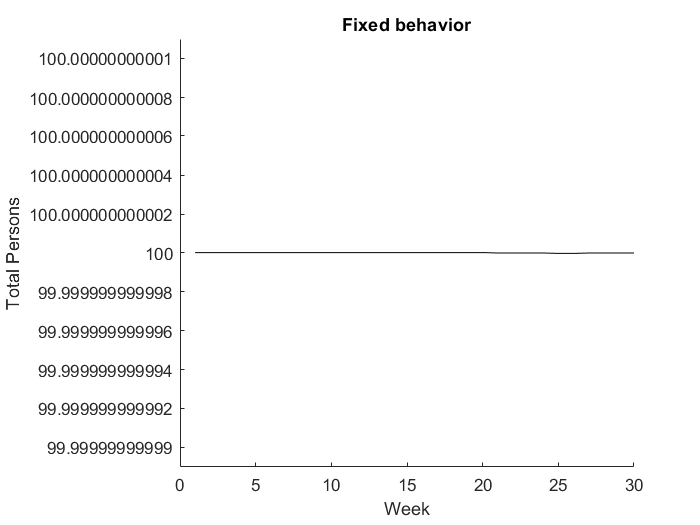

% Run simulation
[S_fix, I_fix, R_fix, W_fix] = sir_simulate_v2(s_0, i_0, r_0, beta, gamma, 30);
T_fix = S_fix + I_fix + R_fix;

% Plot the problematic results
figure(2); clf; hold on;
plot(W_fix, T_fix, 'k-');

xlabel("Week")
ylabel("Total Persons")
title("Fixed behavior")

**Exercise:** What other "facts" about the SIR model could you check?

- We should check that no one should be infected at the end of the flu season.

- We could check that the number of recovered people and number of susceptible people equals the total number of people at the end of flu season (since no one should be infected at the end of the season)

- We should check that the number of susceptible people is decreasing, and the number of recovered people is increasing, over time.

- We should check that the number of susceptible and recovered people levels out to a plateau.

- We should check that the change in number of infected people should never be greater than the number of susceptible people, since that's impossible.

- We should check that the change in number of recovered people should never be greater than the number of infected people, since that's impossible.

When doing model verification, you should decide on a large number of "facts" that should follow from your model definition, but which are *not* a direct consequence of something you coded. For instance, if you set the initial number of infected persons to 2, it's not enough to check that `i_0 = 2`. This sort of check is *necessary* *but not sufficient* for model verification. You should instead look for "facts" that are a resulting property of how you developed the model---the conservation of total persons is one such example.

One last tip: Another great way to verify a model is to give it to someone else and ask if it makes sense. *Peer review* is an excellent way to catch errors (it's what professional scientists do!).

Also remember that *verification* is only half of the model evaluation story; verification just checks that we *implemented* the model correctly. We should also check whether the model is a good representation of reality! To do that, we need to *validate* our model.

**Validation Steps:** To build and validate a physical model, we should follow a set of steps:

- *Clearly state* the purpose for which we want to use our model. This should include the scenario we are studying, and the questions we want to answer.

- Construct our model based on understanding of the physical phenomena at play.

- Use *training data* to fit the parameters in the model and determine if the model is *flexible* enough to represent the data.

- Use *validation data* to assess whether the model is *trustworthy* enough to support answering our questions.

The *validation data* should lie "outside" our training data, in order to test whether our model is *trustworthy *enough to extrapolate outside what we've seen before. This is important for answering the questions we have about the flu: Remember we were interested in answering:

**Questions**

- When will this flu season be over?

- How many of the 100 total persons will fall ill with the flu?

The training phase results are encouraging, in that they indicate the model can fit behaviors we've seen before. But what about something we haven't seen before? To test if the model is valid for predicting results in the future, we need to check it against data not used in fitting to see if the model as-fit can predict future results. To that end, let's load some additional data to serve validation purposes.

% Load the validation data
tab_data_validate = readtable("wave1.csv", "Delimiter", ",")

tab_data_validate = 18×2 table
    W     I 
    __    __

     1     2
     2     3
     3     5
     4     8
     5    11
     6    16
     7    20
     8    23
     9    23
    10    20
    11    16
    12    12
    13     8
    14     6
    15     4
    16     3


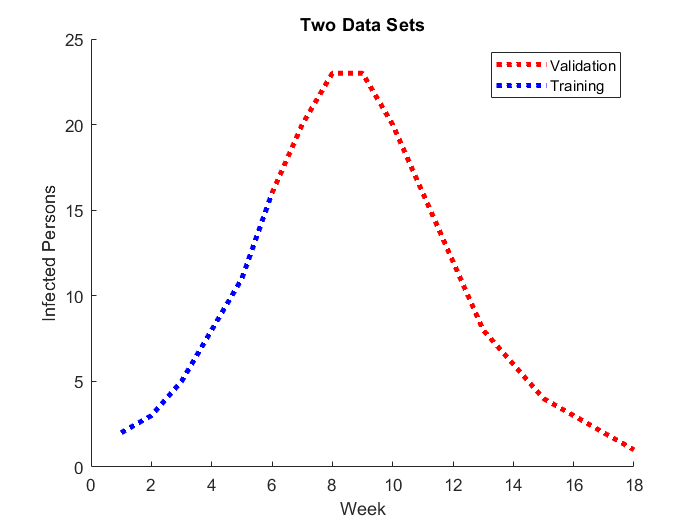


% Plot the training and validation data
figure(2); clf; hold on;
plot(tab_data_validate.W, tab_data_validate.I, 'r:', 'LineWidth', 3); label1 = "Validation";
plot(tab_data_train.W, tab_data_train.I, 'b:', 'LineWidth', 3); label2 = "Training";

xlabel("Week")
ylabel("Infected Persons")
legend({label1, label2})
title("Two Data Sets")

Notice that the validation data extends beyond the training data. It's important that we do not touch the validation data at all when fitting the model.

Now let's complete the validation exercise by comparing the model against the validation data.

**Exercise:** Create a plot of `tab_data_validate` against the simulation results `W_fit, I_fit`. Is the model sufficiently accurate for predicting a few weeks into the future?

*Hint:* See the code above for a hint on how to plot data using a Matlab table.

% Load the training data
tab_data_train = readtable("wave1.csv", "Delimiter", ",")

tab_data_train = 18×2 table
    W     I 
    __    __

     1     2
     2     3
     3     5
     4     8
     5    11
     6    16
     7    20
     8    23
     9    23
    10    20
    11    16
    12    12
    13     8
    14     6
    15     4
    16     3


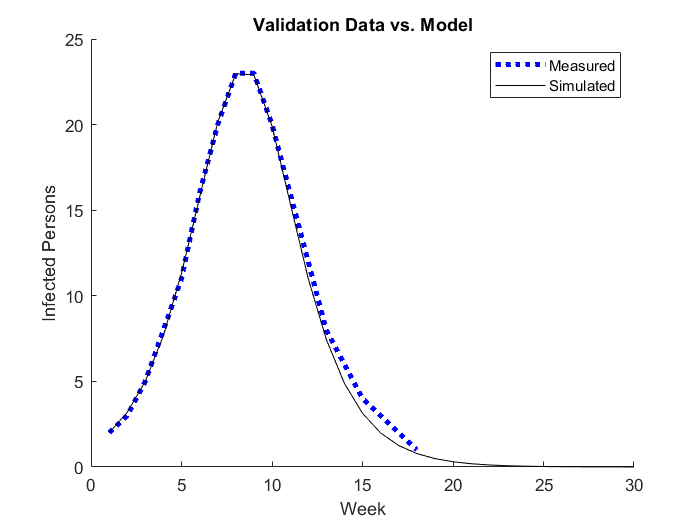


beta = 1 / 89.5; % Infection rate (New / Susceptible / Infected / day)
gamma = 1 / 2; % Recovery rate (1 / week)
i_0 = 2;       % Initial count of infected persons

% Define initial state
s_0 = 100 - i_0;
r_0 = 0;

% Run simulation
[S_fit, I_fit, R_fit, W_fit] = sir_simulate(s_0, i_0, r_0, beta, gamma, 30);

% Plot the fitted simulation
figure(1); clf; hold on;
plot(tab_data_train.W, tab_data_train.I, 'b:', 'LineWidth', 3); label1 = "Measured";
plot(W_fit, I_fit, 'k-'); label2 = "Simulated";

xlabel("Week")
ylabel("Infected Persons")
legend({label1, label2})
title("Validation Data vs. Model")

**Important Note: **It may seem circular that we're using data from "the future" (beyond Week 6) to validate the model. In real cases of model validation we will take *historical* data, split it into training and validation sets, and perform the same exercise. In that case, it's important to split the data in a way that matches the way you intend to use the model; for instance, if making predictions in the future, make sure your validation data contains information further forward in time than what's contained in your training data.

**A Productive Mindset:** When building a model, we should maintain a healthy degree of skepticism towards our model. Remember, "All models are wrong, some are useful." *Verification* and *Validation* are concrete ways to put that skepticism into practice: 

Verification: By writing down and testing "facts" about our model, we are checking to make sure we did not introduce any bugs when implementing our model in code.

Validation: By "stress testing" our model with data it hasn't seen before, we can get a sense of how well our model will perform when we use it to predict on scenarios we've not yet seen. 

Verification and validation help us build confidence---but not certainty---that our model will be useful. Why should we have confidence but not certainty? Let's take a look at one way things can go wrong---when we're *missing some physics in our model.*

## Missing Physics

We've shown that the model is valid for the purpose of predicting a few weeks into the future. But what about predicting the next flu season? Let's load a second data set to see how well the model performs in that scenario:

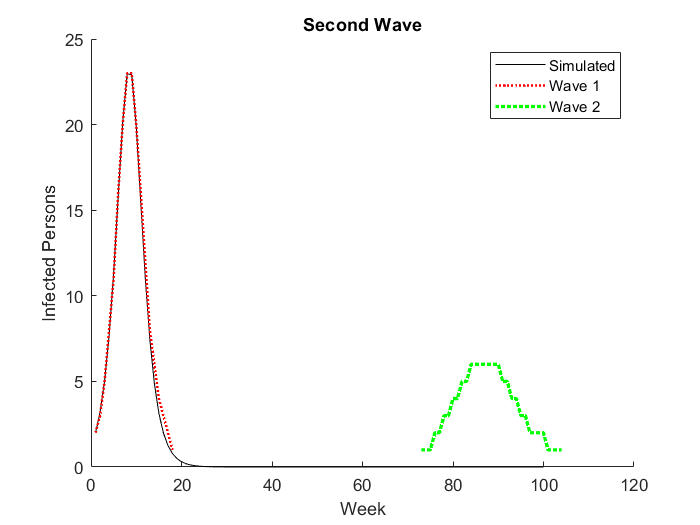

% Load the validation data
tab_data_wave2 = readtable("wave2.csv", "Delimiter", ",");

% Configure the simulation
beta = 1 / 89.5; % Infection rate (New / Susceptible / Infected / day)
gamma = 1 / 2; % Recovery rate (1 / day)
i_0 = 2;       % Initial count of infected persons
s_0 = 100 - i_0;
r_0 = 0;

% Run simulation
[S_long, I_long, R_long, W_long] = sir_simulate_v2(s_0, i_0, r_0, beta, gamma, 100);

% Plot the fitted simulation
figure(3); clf; hold on;

plot(W_long, I_long, 'k-'); label1 = "Simulated";
plot(tab_data_validate.W, tab_data_validate.I, 'r:', 'LineWidth', 1.5); label2 = "Wave 1";
plot(tab_data_wave2.W, tab_data_wave2.I, 'g:', 'LineWidth', 2.0); label3 = "Wave 2";

xlabel("Week")
ylabel("Infected Persons")
legend({label1, label2, label3})
title("Second Wave")

The model is totally invalid for predicting the next flu season! It does not exhibit a second wave at all.

**Exercise:** Try tweaking the parameters `beta, gamma, i_0` to match this second wave phenomena. Convince yourself that it is not possible to represent both the first and second wave with the present model.

% Load the validation data
tab_data_wave2 = readtable("wave2.csv", "Delimiter", ",");

% Configure the simulation
beta = 1 / 140; % Infection rate (New / Susceptible / Infected / day)
gamma = 1 / 2; % Recovery rate (1 / day)
i_0 = 1;       % Initial count of infected persons
s_0 = 100 - i_0;
r_0 = 0;

% Run simulation
[S_long, I_long, R_long, W_long] = sir_simulate_v2(s_0, i_0, r_0, beta, gamma, 100);

% Plot the fitted simulation
figure(3); clf; hold on;

W_long

W_long =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


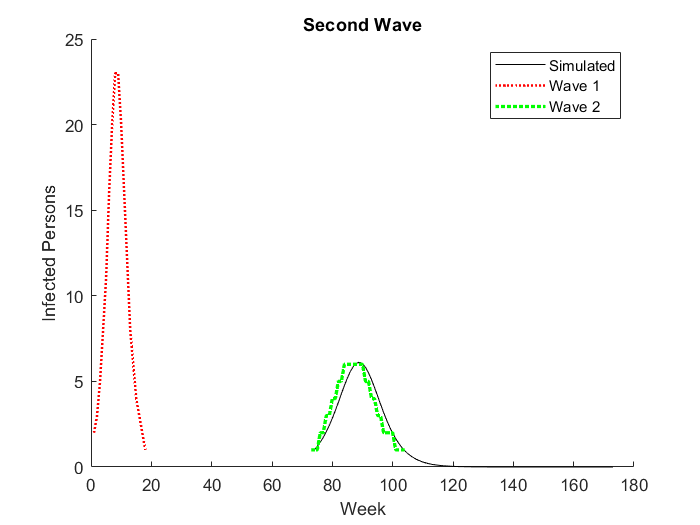


plot(W_long + + 73, I_long, 'k-'); label1 = "Simulated";
plot(tab_data_validate.W, tab_data_validate.I, 'r:', 'LineWidth', 1.5); label2 = "Wave 1";
plot(tab_data_wave2.W, tab_data_wave2.I, 'g:', 'LineWidth', 2.0); label3 = "Wave 2";

xlabel("Week")
ylabel("Infected Persons")
legend({label1, label2, label3})
title("Second Wave")

**Answer: **I have attempted to fit the model to the second wave, and thus have not been able to fit it to the first wave. I am convinced.

Let's think about why our present model can't represent this second wave. Remember the stock and flow diagram for this model:

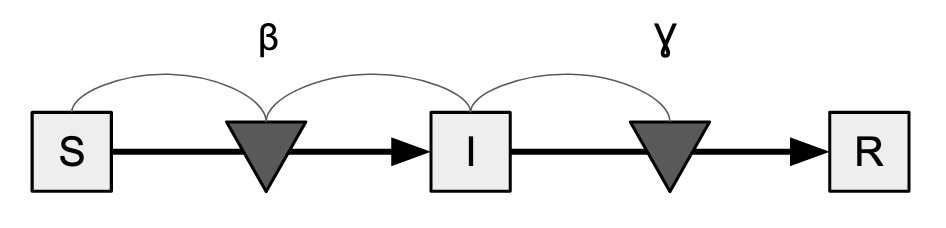

This stock and flow diagram has just two flows, Infections carry individuals from S to I, and Recoveries carry individuals from I to R. In this model *only Susceptible* *persons can become Infected*. 

**Exercise:** Answer the following questions:

- What *physical causes* could lead to a person getting re-infected with the flu? Name two or three possible causes. *Hint:* The US Centers for Disease for Disease Control and Prevention (CDC) publishes articles on [this topic](https://www.cdc.gov/flu/about/viruses/change.htm).

- The flu virus could mutate through antigenic drift (and does tend to mutate every season, which is why we have flu vaccines for each flu season) and therefore even those who have been infected can catch the flu again.

- A new flu virus could emerge through antigenic shift, in which an abrupt, major change in the flu virus occurs - for example, through a flu virus from a given animal species that mutates to be able to infect humans. As a result, humans who were infected with a different flu virus are still able to be infected by the new flu virus.

- How could we *represent* these physical causes in our model? What *additional flow* would you add to the model, what information links would this new flow have, and what physical mechanism would this represent?

We would represent these physical causes in our model by adding a delta susceptible flow from the recovered stock to susceptible people. This flow would depend on the number of recovered people and have a coefficient determined by how well the new flu virus infects those who have already recovered. This would represent the physical mechanism of virus mutations.